%ともかく、固有ベクトルは出ているものする
%固有振動数も出ている

mode_shapes= -1 + (2).*rand(4) 

mode_shapes =     0.3256    0.9768   -0.4243    0.6364
   -0.3383    0.0800   -0.1710   -0.7996
    0.7970    0.4138   -0.0703   -0.6438
   -0.7637    0.9990    0.5279   -0.2807


%{

for mode=1:1:length(mode_shapes(1,:))
    mode_shapes(:,mode)=mode_shapes(:,mode)/max(abs(mode_shapes(:,mode)));
end
%}
%各モードについて、（各点の振幅という意味で）固有ベクトルをいれていく
%列がモード行が点(各列に各モードがはいっている)
f=[20,50,80,123]

f =     20    50    80   123


color=["red","blue","green","cyan","magenta","black","yellow","white"]

color = 1×8 の string 配列
    "red"    "blue"    "green"    "cyan"    "magenta"    "black"    "yellow"    "white"


for i=1:1:length(mode_shapes(1,:))
    hold on
    plot([mode_shapes(:,i)],"--","LineWidth",2,"Color",color(i))
   
end

[mass,K,mode_shapes]=ROM_func(mode_shapes,f)

mass =     1.4085   -0.0000    0.0000    0.0000
   -0.0000    0.4559    0.0000    0.0000
    0.0000    0.0000    1.0972   -0.0000
    0.0000    0.0000   -0.0000    1.7659


K = 	1.0e+05 *

    1.8387   -1.1334   -1.3458   -0.5030
   -1.1334    7.5095    2.6737   -0.1305
   -1.3458    2.6737    2.0820    0.7021
   -0.5030   -0.1305    0.7021    0.7624


mode_shapes =     0.2281    0.8048   -0.5980    0.5925
   -0.2645    0.0291   -0.4668   -0.4088
    0.7719    0.3262    0.1227   -0.6164
   -0.6860    0.8828    0.6701   -0.2586


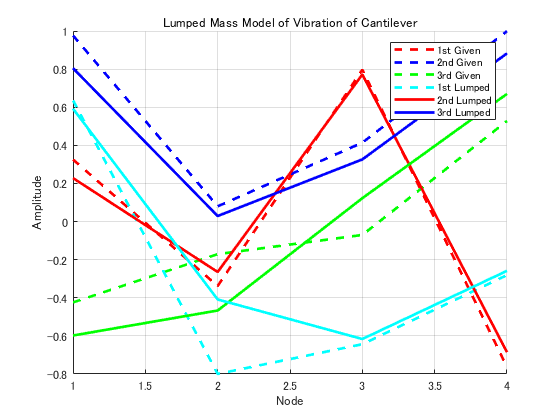

%{
em=equiblim_mass(mode_shapes,mass);
for i=1:1:length(mode_shapes(:,1))
    mode_shapes(:,i)=mode_shapes(:,i)./em(i);
end%等価マスで正規化する

mass=return_M(mode_shapes)
[mass,K,mode_shapes]=ROM_func(mode_shapes,f)
mode_shapes'*mass*mode_shapes
mode_shapes'*K*mode_shapes
%}
for i=1:1:length(mode_shapes(1,:))
    hold on
    plot([mode_shapes(:,i)],"-","LineWidth",2,"Color",color(i))
   
end
title("Lumped Mass Model of Vibration of Cantilever")
xlabel("Node")

ylabel("Amplitude")
legend("1st Given","2nd Given","3rd Given","1st Lumped","2nd Lumped","3rd Lumped")
grid on